clear all
close all

addpath("Immagini\06_binning")

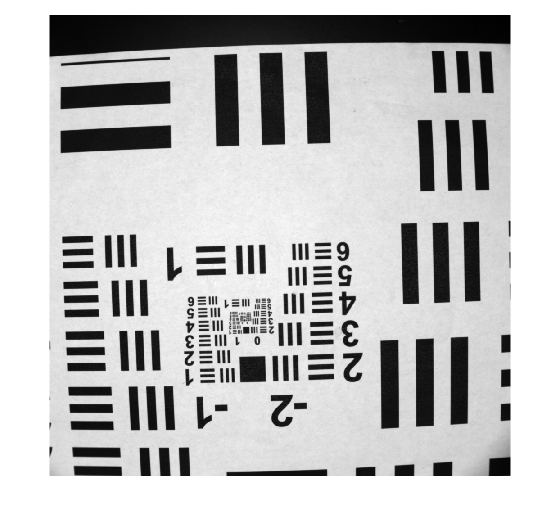

im_1 = importdata("Risoluzione_B1_t2_f4.asc");
im_1 = im_1(:,2:end);

noise_1 = importdata("Risoluzione_buio_B1_t2_f4.asc");
noise_1 = noise_1(:,2:end);

im_1 = im_1 - noise_1;

imshow(im_1,[])

x = [425  481];
y = [-816 -815];

pixel_dist = round(sqrt((x(1)-x(2))^2 + (y(1)-y(2))^2))

pixel_dist = 56

conv_factor = pixel_dist/10 % pixel/mm

conv_factor = 5.6000

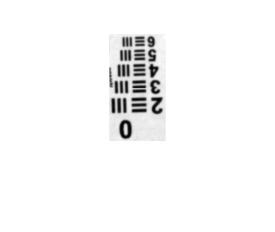

group_0 = im_1(628:735,446:502);
imshow(group_0, [])

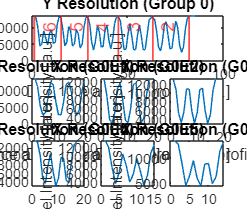


subplot(3,3,[1,2,3]);
y_res0 = improfile(group_0, [33 33], [1 85]);
plot(y_res0)
title("Y Resolution (Group 0)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along y profile [a.u.]")
xline(82, 'LineWidth', 1, 'Color', 'r')
xline(63, 'LineWidth', 1, 'Color', 'r', 'Label', '2')
xline(45, 'LineWidth', 1, 'Color', 'r', 'Label', '3')
xline(29, 'LineWidth', 1, 'Color', 'r', 'Label', '4')
xline(15, 'LineWidth', 1, 'Color', 'r', 'Label', '5')
xline(1, 'LineWidth', 1, 'Color', 'r', 'Label', '6')

subplot(3,3,4);
x_res01 = improfile(im_1, [427 446], [639 639]);
plot(x_res01)
title("X Resolution (G0E1)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,5);
x_res02 = improfile(group_0, [2 19], [73 73]);
plot(x_res02)
title("X Resolution (G0E2)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,6);
x_res03 = improfile(group_0, [5 21], [55 55]);
plot(x_res03)
title("X Resolution (G0E3)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,7);
x_res04 = improfile(group_0, [7 23], [37 37]);
plot(x_res04)
title("X Resolution (G0E4)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,8);
x_res05 = improfile(group_0, [10 24], [22 22]);
plot(x_res05)
title("X Resolution (G0E5)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,9);
x_res06 = improfile(group_0, [12 25], [8 8]);
plot(x_res06)
title("X Resolution (G0E6)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

close all hidden;

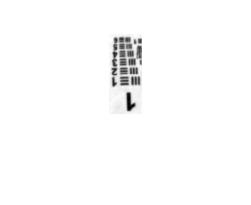

group_1 = im_1(657:737,397:429);
imshow(group_1, [])

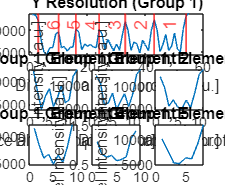


subplot(3,3,[1,2,3]);
y_res1 = improfile(group_1, [14 14], [1 55]);
plot(y_res1)
title("Y Resolution (Group 1)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along y profile [a.u.]")
xline(54, 'LineWidth', 1, 'Color', 'r')
xline(43, 'LineWidth', 1, 'Color', 'r', 'Label', '1')
xline(33, 'LineWidth', 1, 'Color', 'r', 'Label', '2')
xline(24, 'LineWidth', 1, 'Color', 'r', 'Label', '3')
xline(16, 'LineWidth', 1, 'Color', 'r', 'Label', '4')
xline(10, 'LineWidth', 1, 'Color', 'r', 'Label', '5')
xline(3, 'LineWidth', 1, 'Color', 'r', 'Label', '6')

subplot(3,3,4);
x_res11 = improfile(group_1, [22 33], [48 48]);
plot(x_res11)
title("Group 1, Element 1")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,5);
x_res12 = improfile(group_1, [20 31], [37 37]);
plot(x_res12)
title("Group 1, Element 2")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,6);
x_res13 = improfile(group_1, [19 29], [29 29]);
plot(x_res13)
title("Group 1, Element 3")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,7);
x_res14 = improfile(group_1, [18 26], [20 20]);
plot(x_res14)
title("Group 1, Element 4")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,8);
x_res15 = improfile(group_1, [17 25], [13 13]);
plot(x_res15)
title("Group 1, Element 5")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,9);
x_res16 = improfile(group_1, [16 23], [7 7]);
plot(x_res16)
title("Group 1, Element 6")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

group_y = 1;
element_y = 5;

r_y = 2^(group_y+(element_y-1)/6);
R_y = 1/r_y

R_y = 0.3150


group_x = 1;
element_x = 4;

r_x = 2^(group_x+(element_x-1)/6);
R_x = 1/r_x

R_x = 0.3536